## **1. Завантаження кольорових і ч/б зображень з бібліотеки MATLAB**

imgCol1 = imread('peppers.png');
imgGray1 = imread('cameraman.tif');

## 2. Перетворення кольорових в чорнобілі та вивід зображень

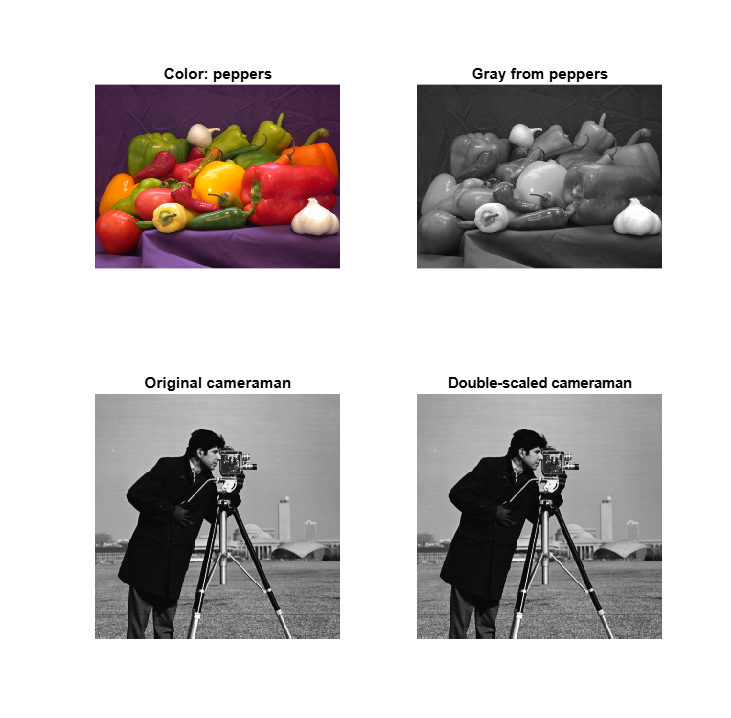

gray1 = im2double(rgb2gray(imgCol1));
gray3 = im2double(imgGray1);

figure;
subplot(2,2,1), imshow(imgCol1), title('Color: peppers');
subplot(2,2,2), imshow(gray1),   title('Gray from peppers');
subplot(2,2,3), imshow(imgGray1),title('Original cameraman');
subplot(2,2,4), imshow(gray3),   title('Double-scaled cameraman');
truesize;

## 3.  Поблочне ДКП (розмір блока — 8×8)

% розмір блока та матриця коефіцієнтів ДКП
blkSize = 8;
dctM = dctmtx(blkSize);

% процедура
dctFun  = @(bs) dctM * bs.data * dctM';     % пряме ДКП

% поблочна обробка зображень
coeffsA = blockproc(gray1, [blkSize blkSize], dctFun);
coeffsB = blockproc(gray3, [blkSize blkSize], dctFun);

## 4.Відображення спектрів ДКП в логарифмічному масштабі

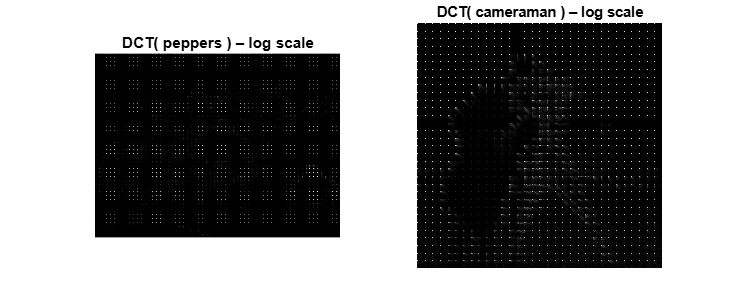

figure;
subplot(1,2,1), imshow( log(abs(coeffsA)+1), [] ), title('DCT( peppers ) – log scale');
subplot(1,2,2), imshow( log(abs(coeffsB)+1), [] ), title('DCT( cameraman ) – log scale');
truesize;

Пояснення: Логарифмічне відображення дозволяє «підняти» слабкі (високочастотні) коефіцієнти, які при лінійному масштабі практично «згасають» на фоні сильніших низьких частот.

## 5. Зворотне ДКП

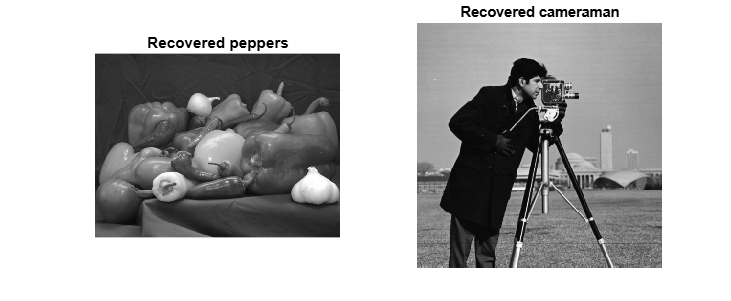

idctFun = @(bs) dctM' * bs.data * dctM;      % зворотнє ДКП
rec1 = blockproc(coeffsA, [blkSize blkSize], idctFun);
rec2 = blockproc(coeffsB, [blkSize blkSize], idctFun);

figure;
subplot(1,2,1), imshow(rec1), title('Recovered peppers');
subplot(1,2,2), imshow(rec2), title('Recovered cameraman');
truesize;

## 6. Квантування результатів ДКП з різними кроками (N = 0.1, 0.5, 1, 5)

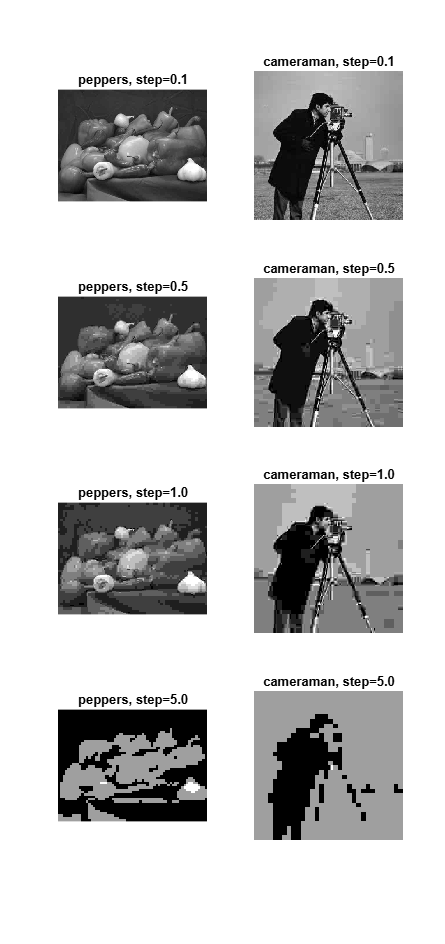

stepSizes = [0.1, 0.5, 1, 5];
figure;
for k = 1:numel(stepSizes)
    s = stepSizes(k);
    
    % квантуємо коефіцієнти
    qA = s * round(coeffsA / s);
    qB = s * round(coeffsB / s);
    
    % відновлюємо після квантування
    rq1 = blockproc(qA, [blkSize blkSize], idctFun);
    rq2 = blockproc(qB, [blkSize blkSize], idctFun);
    
    subplot(numel(stepSizes),2,(k-1)*2+1), imshow(rq1), title(sprintf('peppers, step=%.1f',s));
    subplot(numel(stepSizes),2,(k-1)*2+2), imshow(rq2), title(sprintf('cameraman, step=%.1f',s));
end
truesize;

Як працює квантування:

Для кожного коефіцієнта J виконується round(J/s) — отримуємо ціле число,

 а потім множимо назад на s. Тобто значення «зкруглюється» до найближчого  кратного s.

## 7. Квантування коефіцієнтів ДКП за маскою

% Маска залишає лише низькі частоти у кожному блоці
quantMask = [
    1 1 1 1 0 0 0 0;
    1 1 1 0 0 0 0 0;
    1 1 0 0 0 0 0 0;
    1 0 0 0 0 0 0 0;
    zeros(4,8)
];
maskedA = blockproc(coeffsA, [blkSize blkSize], @(bs) quantMask .* bs.data);
maskedB = blockproc(coeffsB, [blkSize blkSize], @(bs) quantMask .* bs.data);

## 8.  Відновлення з маскованим спектром

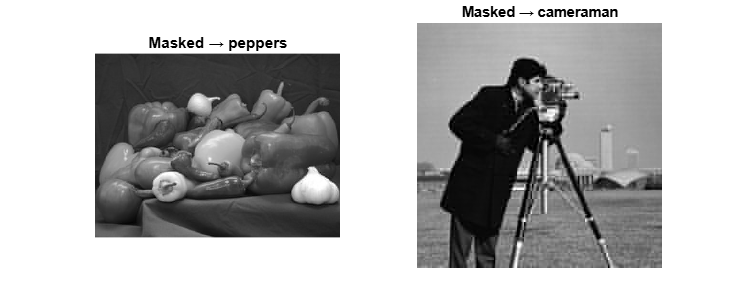

% зворотне перетворення ДКП
recM_A = blockproc(maskedA, [blkSize blkSize], idctFun);
recM_B = blockproc(maskedB, [blkSize blkSize], idctFun);

figure;
subplot(1,2,1), imshow(recM_A), title('Masked → peppers');
subplot(1,2,2), imshow(recM_B), title('Masked → cameraman');
truesize;

## 9. Результат

 Просте квантування (раз на N) дає поступову втрату деталей у міру   збільшення кроку s: чим більше s, тим грубіша «приблизна» картина. 

  Квантування за маскою повністю відкидає високочастотні компоненти,    залишаючи лише загальні форми (низькі частоти). Це дає сильний   ступінь стиснення з втратами (як у JPEG), при цьому зберігається %   візуально важлива інформація (силуети, крупні деталі).